ModelName = 'Solar';
simInp = Simulink.SimulationInput(ModelName);
simInp = simInp.setVariable('irradiance',1000);
simInp = simInp.setVariable('temperature',25);
stopTimestr = num2str(40);
simInp = simInp.setModelParameter('stopTime',stopTimestr);
simInp = simInp.setModelParameter('simulationMode','Rapid');
simOut = sim(simInp);


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 2.0717s


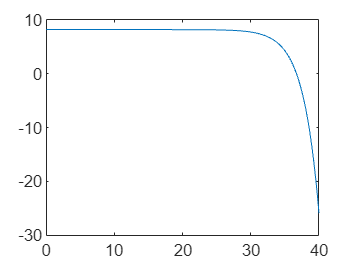

t = simOut.tout;
Current = simOut.yout{1}.Values.Data;
Power = simOut.yout{2}.Values.Data;
Voltage = simOut.yout{3}.Values.Data;
plot(t,squeeze(Current));

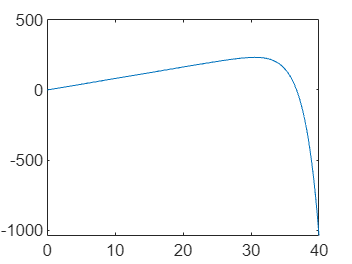

plot(t,squeeze(Power));

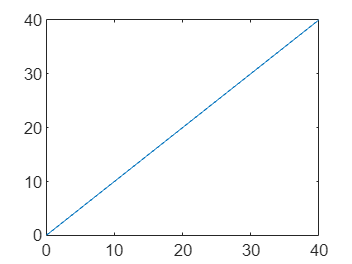

plot(t,squeeze(Voltage));

plot(Voltage,squeeze(Power));